# Problem -1.

### Q.1]

alpha = 1 + mod(276,3);
% Analyze the piano recording
plotMagnitudeSpectrum('piano1.wav');

% Analyze the trumpet recording
plotMagnitudeSpectrum('trumpet1.wav');

% Analyze the violin recording
plotMagnitudeSpectrum('violin1.wav');

% Analyze the flute recording
plotMagnitudeSpectrum('flute1.wav');



### Q.2]


% Load the audio recordings
[piano_signal, fs_piano] = audioread('piano1.wav');
[flute_signal, fs_flute] = audioread('flute1.wav');

% Compute the FFT for both signals
fft_piano = fft(piano_signal);
fft_flute = fft(flute_signal);

% Calculate the magnitude spectrum
magnitude_spectrum_piano = abs(fft_piano);
magnitude_spectrum_flute = abs(fft_flute);

% Find the index of the peak (fundamental harmonic) for both signals
[~, index_piano] = max(magnitude_spectrum_piano);
[~, index_flute] = max(magnitude_spectrum_flute);

% Calculate the corresponding frequency in Hz
frequency_piano = index_piano * (fs_piano / length(piano_signal));
frequency_flute = index_flute * (fs_flute / length(flute_signal));

% Calculate the scaling factor β
beta = frequency_piano / frequency_flute;

% Display the fundamental frequencies and β
fprintf('Fundamental Frequency of Piano (Hz): %.2f\n', frequency_piano);
fprintf('Fundamental Frequency of Flute (Hz): %.2f\n', frequency_flute);
fprintf('Scaling Factor (β) for Flute to Match Piano: %.4f\n', beta);


# Problem -2.


% Record a 3-second snippet of your whistling
fs = 44100; % Sampling frequency (you can adjust this)
recording = audiorecorder(fs, 16, 1); % Initialize audio recorder
disp('Start whistling...');
recordblocking(recording, 3); % Record for 3 seconds
disp('Recording finished.');
reference_audio = getaudiodata(recording); % Get the recorded audio
% Calculate the FFT of the reference audio
N = length(reference_audio);
fft_result = fft(reference_audio);
fft_magnitude = abs(fft_result(1:N/2+1));
frequencies = linspace(0, fs/2, N/2+1);

% Plot the spectrum
figure;
plot(frequencies, fft_magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Reference Whistle Spectrum');

% Find the fundamental frequency using peak picking (you can customize this)
threshold = max(fft_magnitude) * 0.1; % Adjust the threshold
peaks = find(fft_magnitude > threshold);
fundamental_frequency = frequencies(peaks(1)); % Assuming the first peak is the fundamental
fprintf('%.4f\n', fundamental_frequency);

% Test case 1: Successful attempt (matching fundamental frequency)
keylock(fundamental_frequency); % Whistle with the same fundamental frequency as the reference
fprintf('%.4f\n',fundamental_frequency);

% Test case 2: Failed attempt (fundamental frequency does not match)
keylock(fundamental_frequency); % Whistle with a different fundamental frequency
fprintf('%.4f\n',fundamental_frequency);




# Problem -3.

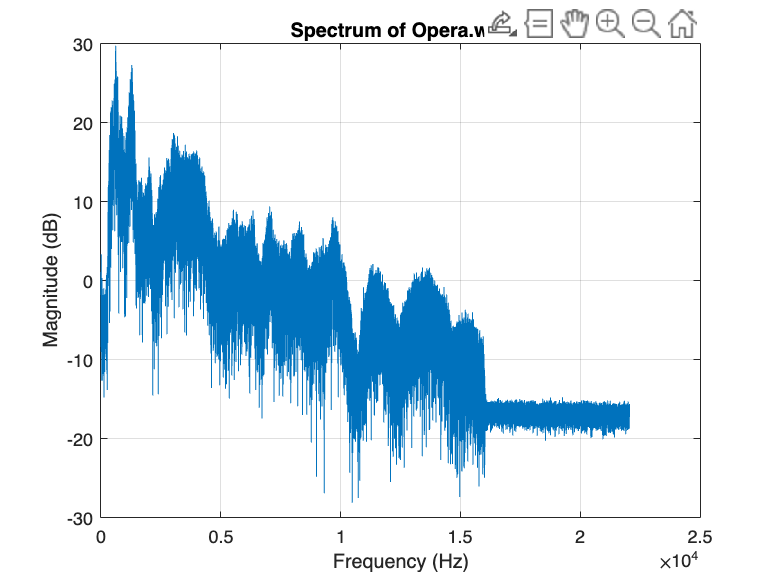


% Load the Opera.wav audio file
[signal, fs] = audioread('Opera.wav');

% Compute the FFT
N = length(signal);
fft_result = fft(signal);

% Calculate the magnitude spectrum
magnitude_spectrum = abs(fft_result);

% Calculate the corresponding frequencies
frequencies = linspace(0, fs/2, N/2+1);

% Plot the spectrum
figure;
plot(frequencies, 10*log10(magnitude_spectrum(1:N/2+1))); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectrum of Opera.wav');
grid on;

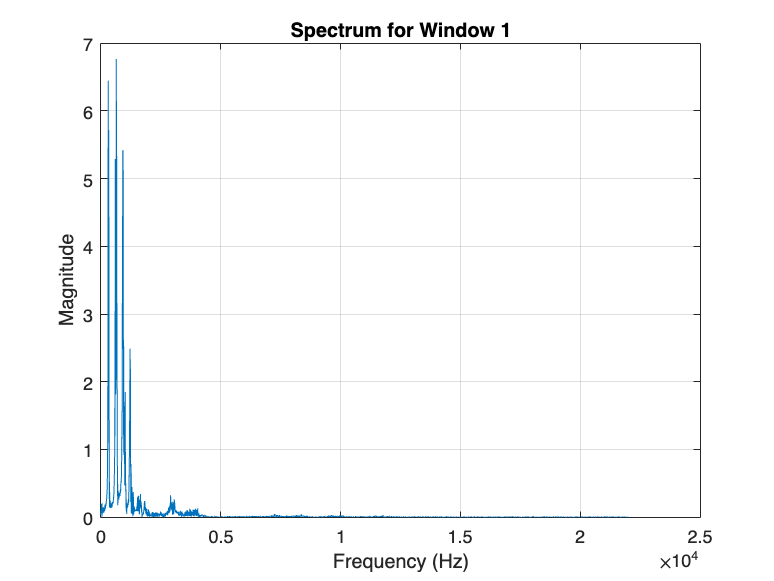

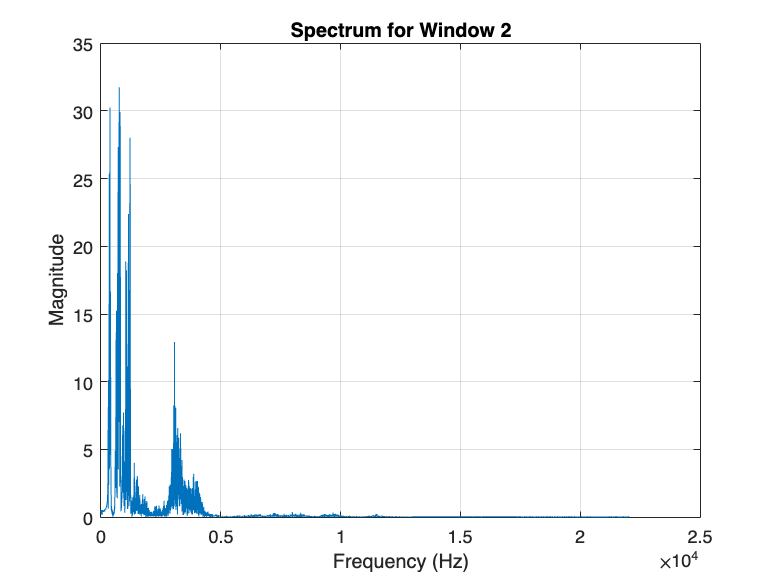

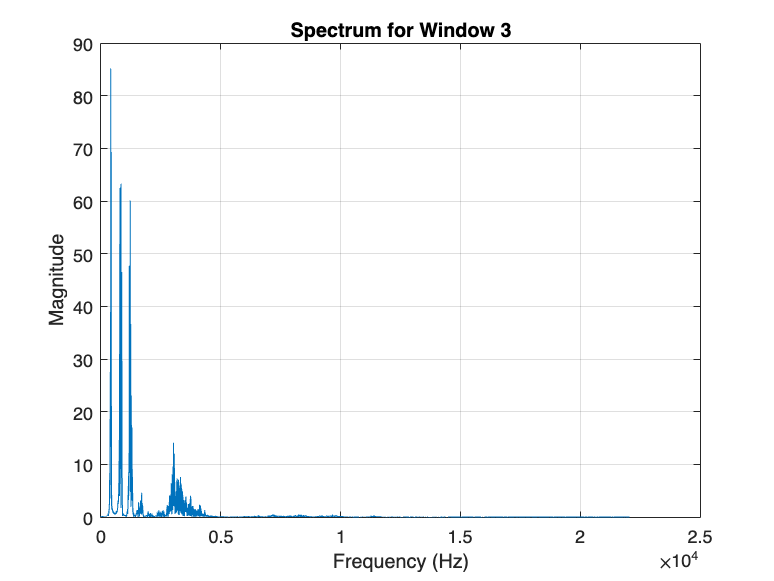

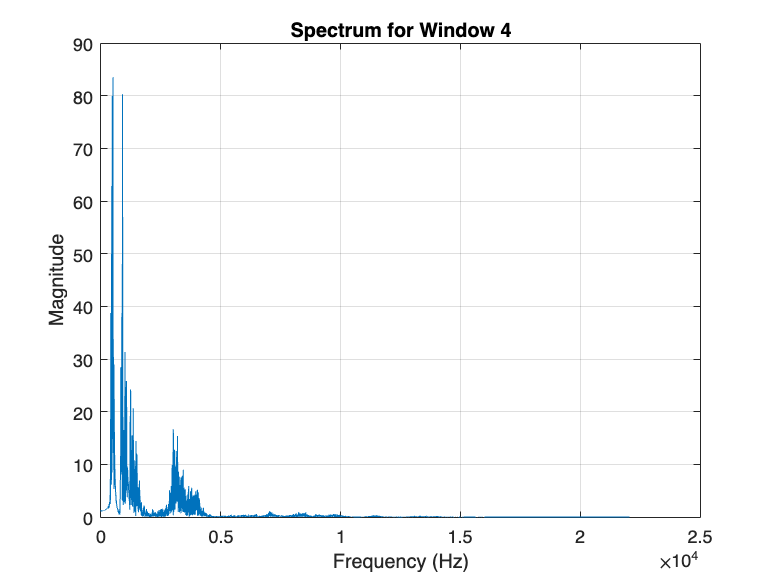

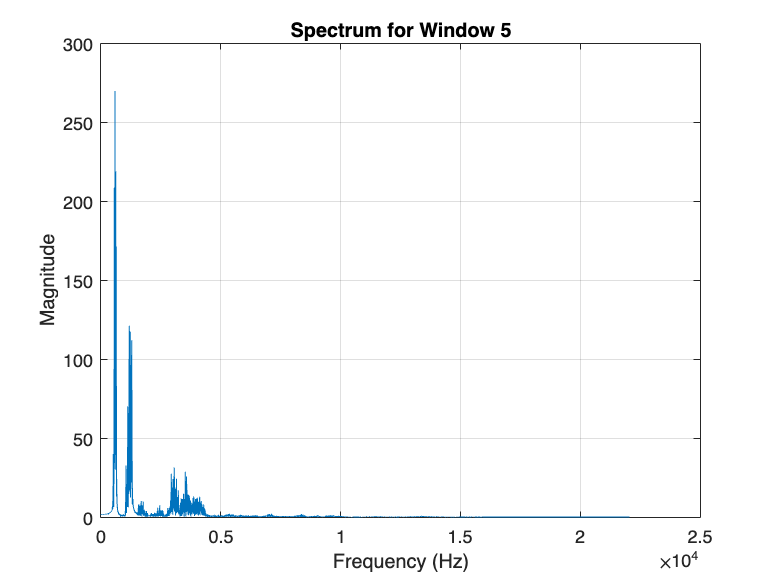

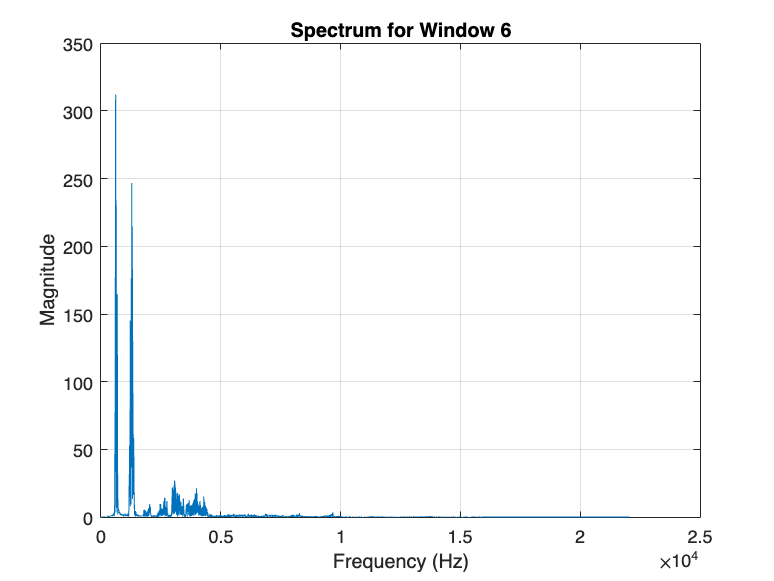

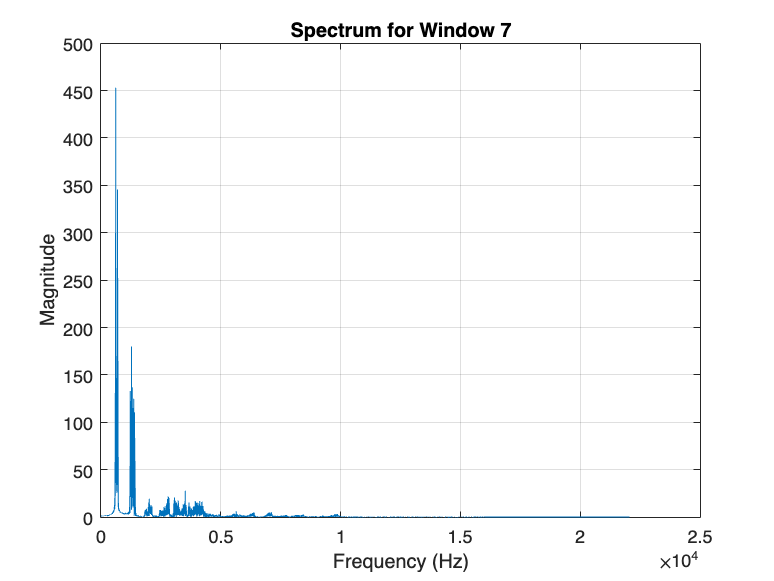

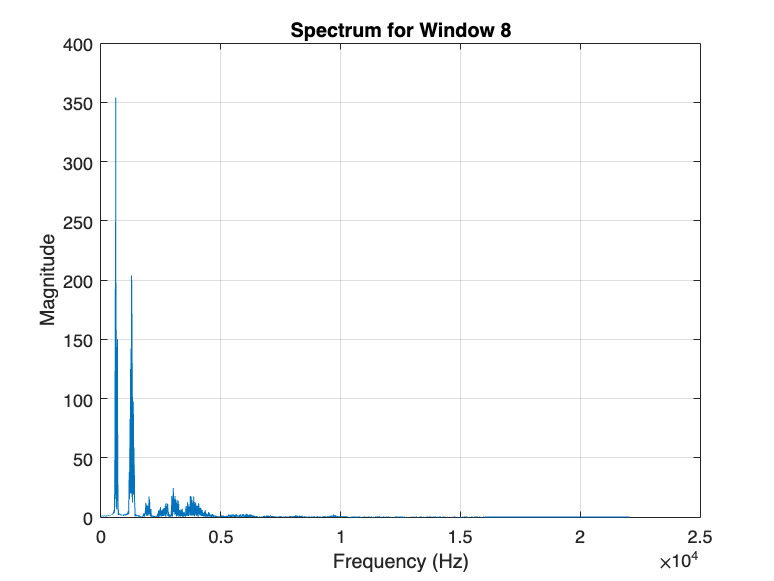


% Define the window size (20,000 samples) for spectral analysis
window_size = 20000;

% Calculate the number of windows
num_windows = floor(length(signal) / window_size);

% Initialize a matrix to store spectral data for each window
spectral_data = zeros(window_size / 2 + 1, num_windows);

% Calculate and plot the spectrum for each window
for i = 1:num_windows
    start_sample = (i - 1) * window_size + 1;
    end_sample = i * window_size;

    % Extract the windowed segment of the signal
    windowed_signal = signal(start_sample:end_sample);

    % Compute the FFT of the windowed segment
    N = length(windowed_signal);
    fft_result = fft(windowed_signal);
    fft_magnitude = abs(fft_result(1:N/2+1));
    frequencies = linspace(0, fs/2, N/2+1);

    % Store the spectral data for this window
    spectral_data(:, i) = fft_magnitude;

    % Plot the spectrum for this window
    figure;
    plot(frequencies, fft_magnitude);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Spectrum for Window ', num2str(i)]);
    grid on;
end